%jan 2021

% ex 8
syms x real positive 
beta = -20

beta = -20

p0 = [-0.8; 1.1]

p0 =    -0.8000
    1.1000



% y = m(x-x0) + y0
y = tan(deg2rad(beta))*(x-p0(1))+ p0(2)

$$y = \frac{4553273276219211}{5629499534213120}-\frac{1639176211415221\,x}{4503599627370496}$$


clf
hold on
fprintf("acceleration")

acceleration

func = y

$$func = \frac{4553273276219211}{5629499534213120}-\frac{1639176211415221\,x}{4503599627370496}$$

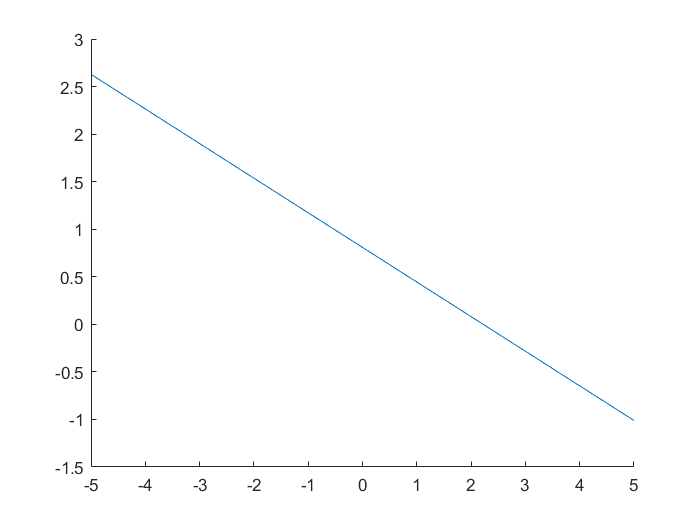

fplot(func, [-5, 5])
hold off 

syms x y real

beta = deg2rad(-20)

beta = -0.3491

R = 0.5+0.4

R = 0.9000

x0 = -0.8

x0 = -0.8000

y0=1.1

y0 = 1.1000


eq_1 = x^2 + y^2 == R^2

$$eq\_1 = x^{2}+y^{2}=\frac{81}{100}$$

eq_2 = y == tan(beta)*(x-x0)+y0

$$eq\_2 = y=\frac{4553273276219211}{5629499534213120}-\frac{1639176211415221\,x}{4503599627370496}$$

sol = solve([eq_1 eq_2], [x, y], 'ReturnConditions',true)

sol = struct with fields:
             x: [2×1 sym]
             y: [2×1 sym]
    parameters: [1×0 sym]
    conditions: [2×1 sym]



x_1 = simplify(sol.x(1))

$$x\_1 = \frac{6755399441055744\,\sqrt{2221824534070620683025559857577931714303224813478897}}{703018976197563667487948056360300631620715}+\frac{29854468953804709501658152042524}{114846541278606138580674608824285}$$

y_1 = simplify(sol.y(1))

$$y\_1 = \frac{82024479320387504662321639194624}{114846541278606138580674608824285}-\frac{803337\,\sqrt{2221824534070620683025559857577931714303224813478897}}{229693082557212277161349217648570}$$


x_2 = simplify(sol.x(2))

$$x\_2 = \frac{29854468953804709501658152042524}{114846541278606138580674608824285}-\frac{6755399441055744\,\sqrt{2221824534070620683025559857577931714303224813478897}}{703018976197563667487948056360300631620715}$$

y_2 = simplify(sol.y(2))

$$y\_2 = \frac{803337\,\sqrt{2221824534070620683025559857577931714303224813478897}}{229693082557212277161349217648570}+\frac{82024479320387504662321639194624}{114846541278606138580674608824285}$$



p_1 = [subs(x_1);subs(y_1)]

$$p\_1 = \left(\begin{array}{c} \frac{6755399441055744\,\sqrt{2221824534070620683025559857577931714303224813478897}}{703018976197563667487948056360300631620715}+\frac{29854468953804709501658152042524}{114846541278606138580674608824285}\\ \frac{82024479320387504662321639194624}{114846541278606138580674608824285}-\frac{803337\,\sqrt{2221824534070620683025559857577931714303224813478897}}{229693082557212277161349217648570} \end{array}\right)$$

p_2 = [subs(x_2);subs(y_2)]

$$p\_2 = \left(\begin{array}{c} \frac{29854468953804709501658152042524}{114846541278606138580674608824285}-\frac{6755399441055744\,\sqrt{2221824534070620683025559857577931714303224813478897}}{703018976197563667487948056360300631620715}\\ \frac{803337\,\sqrt{2221824534070620683025559857577931714303224813478897}}{229693082557212277161349217648570}+\frac{82024479320387504662321639194624}{114846541278606138580674608824285} \end{array}\right)$$


p_start = p_2

$$p\_start = \left(\begin{array}{c} \frac{29854468953804709501658152042524}{114846541278606138580674608824285}-\frac{6755399441055744\,\sqrt{2221824534070620683025559857577931714303224813478897}}{703018976197563667487948056360300631620715}\\ \frac{803337\,\sqrt{2221824534070620683025559857577931714303224813478897}}{229693082557212277161349217648570}+\frac{82024479320387504662321639194624}{114846541278606138580674608824285} \end{array}\right)$$

v = 0.3

v = 0.3000

T = 2

T = 2

L = v*T

L = 0.6000


Dy = L*sin(-beta);
Dx = L*cos(-beta);

p_rv = p_start + [Dx; -Dy]

$$p\_rv = \left(\begin{array}{c} \frac{426070867171579918309844487956839738315305395809}{517222840507120892949394937629006454412657295360}-\frac{6755399441055744\,\sqrt{2221824534070620683025559857577931714303224813478897}}{703018976197563667487948056360300631620715}\\ \frac{803337\,\sqrt{2221824534070620683025559857577931714303224813478897}}{229693082557212277161349217648570}+\frac{2106120291820985100851747106075804183757128922667}{4137782724056967143595159501032051635301258362880} \end{array}\right)$$

double(p_rv)

ans =     0.3708
    0.6739


syms q1 q2 dq1 dq2 'real'

% length l
l1=0.5

l1 = 0.5000

l2=0.4

l2 = 0.4000


% p in planar 2R
r=[l1*cos(q1)+l2*cos(q1+q2);
    l1*sin(q1)+l2*sin(q1+q2)]

$$r = \left(\begin{array}{c} \frac{2\,\cos\left(q_{1}+q_{2}\right)}{5}+\frac{\cos\left(q_{1}\right)}{2}\\ \frac{2\,\sin\left(q_{1}+q_{2}\right)}{5}+\frac{\sin\left(q_{1}\right)}{2} \end{array}\right)$$


% jacobian
J=jacobian(r,[q1 q2])

$$J = \left(\begin{array}{cc} -\frac{2\,\sin\left(q_{1}+q_{2}\right)}{5}-\frac{\sin\left(q_{1}\right)}{2} & -\frac{2\,\sin\left(q_{1}+q_{2}\right)}{5}\\ \frac{2\,\cos\left(q_{1}+q_{2}\right)}{5}+\frac{\cos\left(q_{1}\right)}{2} & \frac{2\,\cos\left(q_{1}+q_{2}\right)}{5} \end{array}\right)$$


% time derivative of the Jacobian
Jder=[-l1*cos(q1)*dq1-l2*cos(q1+q2)*(dq1+dq2) -l2*cos(q1+q2)*(dq1+dq2);
    -l1*sin(q1)*dq1-l2*sin(q1+q2)*(dq1+dq2) -l2*sin(q1+q2)*(dq1+dq2)];


%% Inverse kinematic
% x of p and y of p
px= p_rv(1)

$$px = \frac{426070867171579918309844487956839738315305395809}{517222840507120892949394937629006454412657295360}-\frac{6755399441055744\,\sqrt{2221824534070620683025559857577931714303224813478897}}{703018976197563667487948056360300631620715}$$

py= p_rv(2)

$$py = \frac{803337\,\sqrt{2221824534070620683025559857577931714303224813478897}}{229693082557212277161349217648570}+\frac{2106120291820985100851747106075804183757128922667}{4137782724056967143595159501032051635301258362880}$$


%%  q2
% second joint computations
c2=(px^2+py^2-l1^2-l2^2)/(2*l1*l2);
    s2pos=simplify(sqrt(1-c2^2));  
    %other solution: -sqrt(1-c2^2)
    s2neg= simplify(-sqrt(1-c2^2));  

%% q1
% first joint computations
detM=l1^2+l2^2+2*l1*l2*c2;

% positive solution of q1
s1pos=simplify((py*(l1+l2*c2)-px*l2*s2pos)/detM);
c1pos=simplify((px*(l1+l2*c2)+py*l2*s2pos)/detM);

% negative solution of q1
s1neg=simplify((py*(l1+l2*c2)-px*l2*s2neg)/detM);
c1neg=simplify((px*(l1+l2*c2)+py*l2*s2neg)/detM);

% output positive
fprintf("Positive configuration\n")

Positive configuration


q01p=simplify(atan2(s1pos,c1pos));
q02p=simplify(atan2(s2pos,c2));
q0p=[q01p; q02p]

    double(q0p)

ans =     0.5859
    1.0996


%q0p=double([q01p; q02p])

fprintf("Negative configuration\n")

Negative configuration


% output negative
q01n=simplify(atan2(s1neg,c1neg));
q02n=simplify(atan2(s2neg,c2));
q0n =[q01n;q02n]

    double(q0n)

ans =     1.5495
   -1.0996


%q0n=double([q01n; q02n])

q_rv = q0n


v_vect = v * [cos(-beta); -sin(-beta)]

v_vect =     0.2819
   -0.1026



j_rv = simplify(subs(J, {q1, q2}, {double(q_rv(1)), double(q_rv(2))}))

$$j\_rv = \left(\begin{array}{cc} -\frac{\sin\left(\frac{3489196623557435}{2251799813685248}\right)}{2}-\frac{2\,\sin\left(\frac{1013186847201829}{2251799813685248}\right)}{5} & -\frac{2\,\sin\left(\frac{1013186847201829}{2251799813685248}\right)}{5}\\ \frac{\cos\left(\frac{3489196623557435}{2251799813685248}\right)}{2}+\frac{2\,\cos\left(\frac{1013186847201829}{2251799813685248}\right)}{5} & \frac{2\,\cos\left(\frac{1013186847201829}{2251799813685248}\right)}{5} \end{array}\right)$$

double(j_rv)

ans =    -0.6739   -0.1740
    0.3708    0.3602



A = j_rv;
B = v_vect 

B =     0.2819
   -0.1026


x = simplify(linsolve(A,B))

$$x = \left(\begin{array}{c} -\frac{20313596816708264\,\cos\left(\frac{1013186847201829}{2251799813685248}\right)-7393544592166489\,\sin\left(\frac{1013186847201829}{2251799813685248}\right)}{36028797018963968\,\sin\left(\frac{1238004888177803}{1125899906842624}\right)}\\ \frac{101567984083541320\,\cos\left(\frac{3489196623557435}{2251799813685248}\right)+81254387266833056\,\cos\left(\frac{1013186847201829}{2251799813685248}\right)-36967722960832445\,\sin\left(\frac{3489196623557435}{2251799813685248}\right)-29574178368665956\,\sin\left(\frac{1013186847201829}{2251799813685248}\right)}{144115188075855872\,\sin\left(\frac{1238004888177803}{1125899906842624}\right)} \end{array}\right)$$


q_rv_dot = x

$$q\_rv\_dot = \left(\begin{array}{c} -\frac{20313596816708264\,\cos\left(\frac{1013186847201829}{2251799813685248}\right)-7393544592166489\,\sin\left(\frac{1013186847201829}{2251799813685248}\right)}{36028797018963968\,\sin\left(\frac{1238004888177803}{1125899906842624}\right)}\\ \frac{101567984083541320\,\cos\left(\frac{3489196623557435}{2251799813685248}\right)+81254387266833056\,\cos\left(\frac{1013186847201829}{2251799813685248}\right)-36967722960832445\,\sin\left(\frac{3489196623557435}{2251799813685248}\right)-29574178368665956\,\sin\left(\frac{1013186847201829}{2251799813685248}\right)}{144115188075855872\,\sin\left(\frac{1238004888177803}{1125899906842624}\right)} \end{array}\right)$$

double(q_rv_dot)

ans =    -0.4696
    0.1986


% cubic polynomial
% cubic polynomial

## Q1

syms tau real
syms a b c d real
syms Dq real
syms qin qfin real
syms vin vfin real
syms T real

qn = a*tau^3 + b*tau^2 +c*tau + d 

$$qn = a\,\tau^{3}+b\,\tau^{2}+c\,\tau +d$$

q_tau = qin + Dq*qn

$$q\_tau = \mathrm{qin}+\mathrm{Dq}\,\left(a\,\tau^{3}+b\,\tau^{2}+c\,\tau +d\right)$$


eq_1 = a+b+c==1

$$eq\_1 = a+b+c=1$$

eq_2 = c==vin*T/Dq 

$$eq\_2 = c=\frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$

eq_3 = 3*a+2*b+c == vfin*T/Dq

$$eq\_3 = 3\,a+2\,b+c=\frac{T\,\mathrm{vfin}}{\mathrm{Dq}}$$


s = solve([eq_1, eq_2, eq_3], [a, b, c])

s = struct with fields:
    a: [1×1 sym]
    b: [1×1 sym]
    c: [1×1 sym]


a = simplify(s.a)

$$a = \frac{T\,\mathrm{vfin}-2\,\mathrm{Dq}+T\,\mathrm{vin}}{\mathrm{Dq}}$$

b = simplify(s.b)

$$b = -\frac{T\,\mathrm{vfin}-3\,\mathrm{Dq}+2\,T\,\mathrm{vin}}{\mathrm{Dq}}$$

c = simplify(s.c)

$$c = \frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$


%input
T = 2

T = 2


qin = pi

qin = 3.1416

qfin = double(q_rv(1))

qfin = 1.5495


vin = 0

vin = 0

vfin = double(q_rv_dot(1))

vfin = -0.4696


Dq = double(qfin-qin);
a = double(subs(a))

a = -1.4100

b = double(subs(b))

b = 2.4100

c = double(subs(c))

c = 0

d = 0

d = 0


syms t real positive 

q_t = subs(q_tau, {tau}, {t/T})

$$q\_t = \mathrm{qin}+\mathrm{Dq}\,\left(\frac{a\,t^{3}}{8}+\frac{b\,t^{2}}{4}+\frac{c\,t}{2}+d\right)$$


clf
hold on
fprintf("pos")

pos

func = subs(q_t)

$$func = \frac{22765871937150657596001760871895\,t^{3}}{81129638414606681695789005144064}-\frac{19455730913720287303604880434685\,t^{2}}{20282409603651670423947251286016}+\pi$$

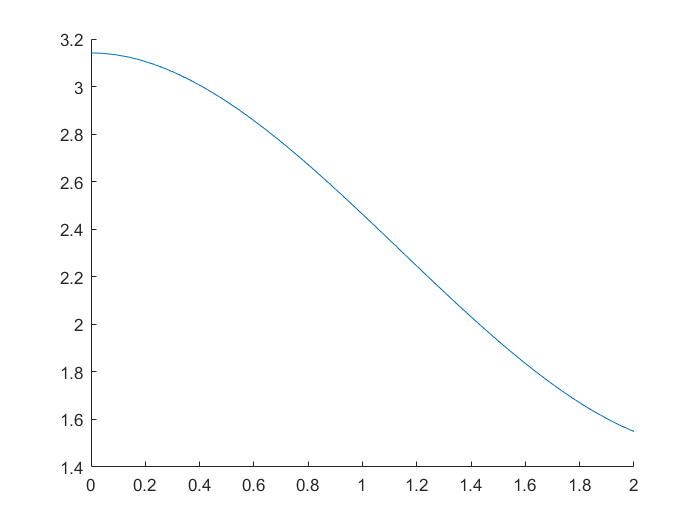

fplot(func, [0,T])
hold off 


clf
hold on
fprintf("vel")

vel

func = subs(diff(q_t, {t}))

$$func = \frac{68297615811451972788005282615685\,t^{2}}{81129638414606681695789005144064}-\frac{19455730913720287303604880434685\,t}{10141204801825835211973625643008}$$

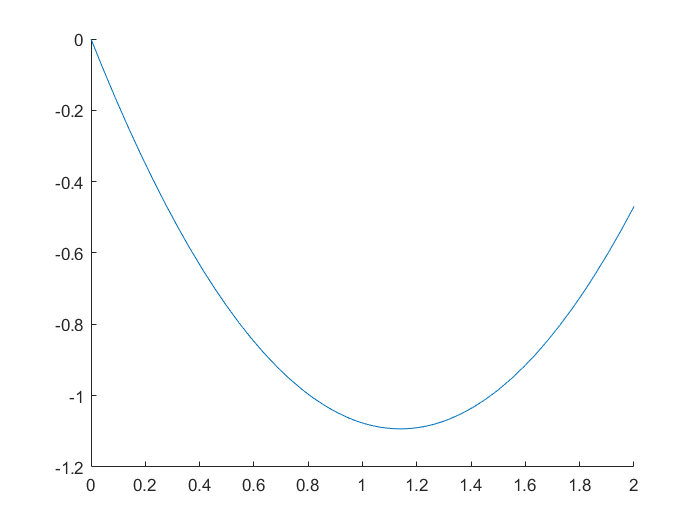

fplot(func, [0,T])
hold off 

## Q2

syms tau real
syms a b c d real
syms Dq real
syms qin qfin real
syms vin vfin real
syms T real

qn = a*tau^3 + b*tau^2 +c*tau + d 

$$qn = a\,\tau^{3}+b\,\tau^{2}+c\,\tau +d$$

q_tau = qin + Dq*qn

$$q\_tau = \mathrm{qin}+\mathrm{Dq}\,\left(a\,\tau^{3}+b\,\tau^{2}+c\,\tau +d\right)$$


eq_1 = a+b+c==1

$$eq\_1 = a+b+c=1$$

eq_2 = c==vin*T/Dq 

$$eq\_2 = c=\frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$

eq_3 = 3*a+2*b+c == vfin*T/Dq

$$eq\_3 = 3\,a+2\,b+c=\frac{T\,\mathrm{vfin}}{\mathrm{Dq}}$$


s = solve([eq_1, eq_2, eq_3], [a, b, c])

s = struct with fields:
    a: [1×1 sym]
    b: [1×1 sym]
    c: [1×1 sym]


a = simplify(s.a)

$$a = \frac{T\,\mathrm{vfin}-2\,\mathrm{Dq}+T\,\mathrm{vin}}{\mathrm{Dq}}$$

b = simplify(s.b)

$$b = -\frac{T\,\mathrm{vfin}-3\,\mathrm{Dq}+2\,T\,\mathrm{vin}}{\mathrm{Dq}}$$

c = simplify(s.c)

$$c = \frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$


%input
T = 2

T = 2


qin = 0

qin = 0

qfin = double(q_rv(2))

qfin = -1.0996


vin = 0

vin = 0

vfin = double(q_rv_dot(2))

vfin = 0.1986


Dq = double(qfin-qin);
a = double(subs(a))

a = -2.3613

b = double(subs(b))

b = 3.3613

c = double(subs(c))

c = 0

d = 0

d = 0



syms t real positive 

q_t = subs(q_tau, {tau}, {t/T})

$$q\_t = \mathrm{qin}+\mathrm{Dq}\,\left(\frac{a\,t^{3}}{8}+\frac{b\,t^{2}}{4}+\frac{c\,t}{2}+d\right)$$


clf
hold on
fprintf("pos")

pos

func = subs(q_t)

$$func = \frac{102854677650847498962377643445\,t^{3}}{316912650057057350374175801344}-\frac{146413102284288172083704239541\,t^{2}}{158456325028528675187087900672}$$

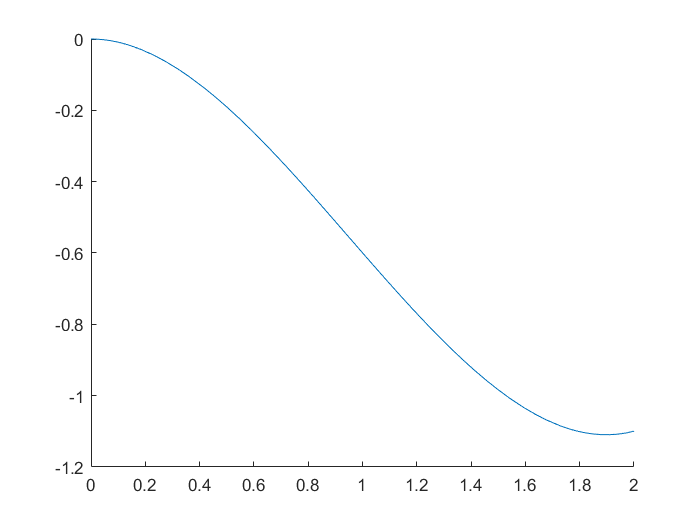

fplot(func, [0,T])
hold off 


clf
hold on
fprintf("vel")

vel

func = subs(diff(q_t, {t}))

$$func = \frac{308564032952542496887132930335\,t^{2}}{316912650057057350374175801344}-\frac{146413102284288172083704239541\,t}{79228162514264337593543950336}$$

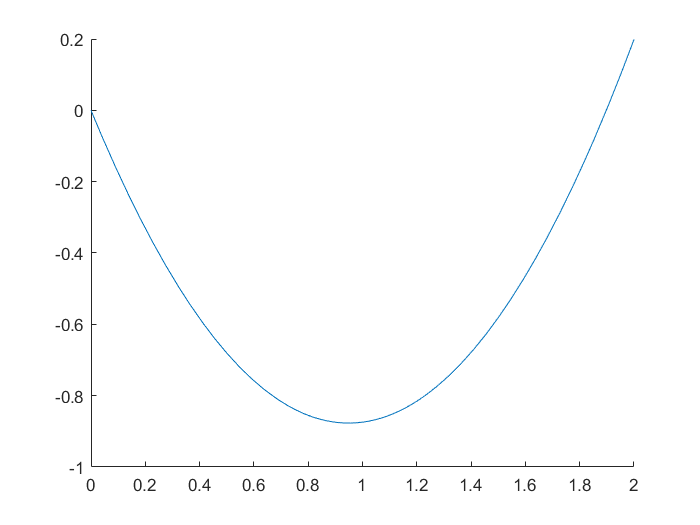

fplot(func, [0,T])
hold off 